# NR Cell Performance Evaluation with Physical Layer Integration

This example shows how to use full physical layer (PHY) processing in system-level simulation. The example models a 5G New Radio (NR) cell consisting of a set of user equipment (UE) nodes connected to a gNB node. The NR stack on the nodes includes radio link control (RLC), medium access control (MAC), and PHY layers. The example also models channel impairments that you can customize. You can also run the example with abstract PHY and compare its performance with that of full PHY.

## Introduction

This example models:

- Full PHY with perfect channel estimation. Use full PHY to model single-cell scenarios.

- Downlink (DL) channel quality measurements performed by UE nodes based on the channel state information reference signal (CSI-RS) received from the gNB. All the UE nodes in the cell use the same CSI-RS resource.

- Uplink (UL) channel quality measurement performed by the gNB node based on the sounding reference signals (SRS) received from the UE nodes. 

- Free space path loss (FSPL).

- Clustered delay line (CDL) propagation channel model for each link. You can customize the channel model configuration.

- Multiple-input multiple-output (MIMO) antenna configuration.

The example assumes that the nodes send the control packets out-of-band. A  source node sends an out-of-band packet directly to the destination node bypassing the channel and without consuming time-frequency resources. The type of control packets include buffer status report (BSR), DL assignment, UL grant, physical downlink shared channel (PDSCH) feedback, and CSI report.

### Physical Layer

The example uses 5G Toolbox™ for PHY layer operations performed by a UE and a gNB. The transmitter-side operations involve the PHY processing of a transport block received from MAC and its transmission. The receiver-side operations include the processing of the received waveform and sending the decoded information to MAC. For more information about the PDSCH and physical uplink shared channel (PUSCH) processing chains, see the [NR PDSCH Throughput](docid:5g_ug#mw_new-radio-pdsch-throughput) and [NR PUSCH Throughput](docid:5g_ug#mw_aec3475a-aecc-4d83-b504-0971620c97eb) examples, respectively.

### Channel Measurement and Reporting

To perform the DL channel measurement, a UE node uses CSI-RS. The gNB, on the other hand, uses SRS to perform the UL channel measurement. For more information about channel measurement and reporting, see the section 'Channel measurement and reporting' in the example [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654).

## Scenario Configuration

Check if the Communications Toolbox Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create the wireless network simulator.

rng("default")                             % Reset the random number generator
numFrameSimulation = 40; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

To use full PHY, set the PHY type, `phyAbstractionType`, to `none`. To use abstract PHY, set `phyAbstractionType` to `linkToSystemMapping`. All the nodes (gNB and UEs) must use the same PHY processing method.

phyAbstractionType = "none";

Create a gNB node. Specify its carrier frequency, channel bandwidth, subcarrier spacing, PHY type, transmit power, number of transmit antennas and receive antennas. Set the SRS transmission periodicity (in slots) for all UEs connecting to this gNB.

gNB = nrGNB(Name="gNB",CarrierFrequency=2.6e9,ChannelBandwidth=5e6,SubcarrierSpacing=15e3,PHYAbstractionMethod=phyAbstractionType, ...
    TransmitPower=34,NumTransmitAntennas=8,NumReceiveAntennas=8,SRSPeriodicityUE=10);

Create four UE nodes. Specify its name, position, transmit power, number of transmit antennas, receive antennas, and PHY type for each UE.

uePositions = [1000 0 0; 4000 0 0; 7000 0 0; 10000 0 0];
ueNames = "UE-" + (1:size(uePositions,1));
UEs = nrUE(Name=ueNames,Position=uePositions,TransmitPower=23,NumTransmitAntennas=2,NumReceiveAntennas=2,PHYAbstractionMethod=phyAbstractionType);

 Create a cell by connecting the UE nodes to the gNB node. Install full buffer traffic in the DL and UL directions and specify the CSI report periodicity (in slots).

connectUE(gNB,UEs,FullBufferTraffic="on",CSIReportPeriodicity=10);

Add the gNB node and UE nodes to the network simulator.

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

Create an *N*-by-*N* array of link-level channels, where *N* is the number of nodes in the cell. An element at index *(i,j)* contains the channel instance from node *i* to node *j*. An empty element at index *(i,j)* indicates that the channel does not exist from node *i* to node *j*. Here, *i* and *j* are the node IDs.

channelConfig = struct("DelayProfile","CDL-C","DelaySpread",300e-9);
channels = hNRCreateCDLChannels(channelConfig,gNB,UEs);

Create a custom channel model using `channels` and install the custom channel on the simulator. The network simulator applies the custom channel to a packet in transit before passing it to the receiver.

customChannelModel = hNRCustomChannelModel(channels,struct(PHYAbstractionMethod=phyAbstractionType));
addChannelModel(networkSimulator,@customChannelModel.applyChannelModel)

### Capture IQ Samples

To capture IQ samples for all the nodes in the simulation, enable the `enableIQSampleCapture` flag. A node only captures the IQ samples transmitted on the node's reception frequency at a time when the node expects a reception. In addition to the signal of interest to the node, the captured IQ samples may include interfering signals. The node captures the IQ samples after the waveform passes through the channel. In the captured output, zeros represent the reception inactivity duration of the node. The reception inactivity means the node did not receive any relevant IQ signal.

Capture the IQ samples of the nodes by using the `helperCaptureIQSamples` helper object. At the end of the simulation, the simulation stores the IQ samples of the corresponding nodes in a MAT file with the filename format `NodeName_NodeID_yyyyMMdd_HHmmss.mat`, where:

- `NodeName` — Name of the node.

- `NodeID` — Numeric ID of the node.

- `yyyyMMdd` — Date of file creation, in the format year, month, day.

- `HHmmss` — Time of file creation, in the format hour, minute, second, using the 24-hour clock format.

The `IQSamples` property of the `iqSampleObj` object contains the captured IQ samples. When you enable the IQ sample capture, the simulation can consume significant memory if many nodes exist or you run the simulation for a long duration. In addition the simulation generates one MAT file per node, which can consume significant disk space. For example, the simulation that captures 100 million samples generates a MAT file of size approximately 1.5 GB. Also, the IQ sample capture can result in longer simulation runtime.

if strcmp(phyAbstractionType,"none") % IQ sample capture only applies to full PHY
    enableIQSampleCapture = false;
    if enableIQSampleCapture
        iqSampleObj = helperCaptureIQSamples.empty;
        % Set up IQ sample capture on gNB
        iqSampleObj(1) = helperCaptureIQSamples(gNB,Bandwidth=gNB.ChannelBandwidth);
        % Set up IQ sample capture on the UEs
        enableIQSampleCaptureUE = false;
        if enableIQSampleCaptureUE
            for ueIdx = 1:numel(UEs)
                iqSampleObj(1+ueIdx) = helperCaptureIQSamples(UEs(ueIdx),Bandwidth=gNB.ChannelBandwidth);
            end
        end
    end
end

### Log Traces

Logging of traces includes information that the example records for analysis after the simulation completes. To enable the logging of traces, set the '`enableTraces'` flag to `true`. You can log this information periodically, like every slot, or in response to specific events. The example supports logging of these traces:

- Periodic logs for the scheduler and PHY for each slot.

- Logs of scheduling assignments, which are event-based and occur when the scheduler issues DL and UL grants to the UEs.

For information on the format of the logged information, see the [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654) example.

If you set the `enableTraces` flag to `false`, the simulation does not log any traces.

enableTraces = true;

Set up the scheduling logger and the PHY logger.

if enableTraces
    % Create an object to log scheduler traces
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object to log PHY traces
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UEs);
end

Set the number of updates for the metrics plot per second, `numMetricPlotUpdates`, during the simulation. The example periodically updates the metrics plots.

numMetricPlotUpdates = 25;

Set up the metric visualizer.

metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=numMetricPlotUpdates,...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true);

Write the logs to a MAT-file. You can use these logs for post-simulation analysis.

simulationLogFile = "simulationLogs"; % For logging the simulation traces

## Simulation and Performance Analysis

Run the simulation for the specified `numFrameSimulation` frames.

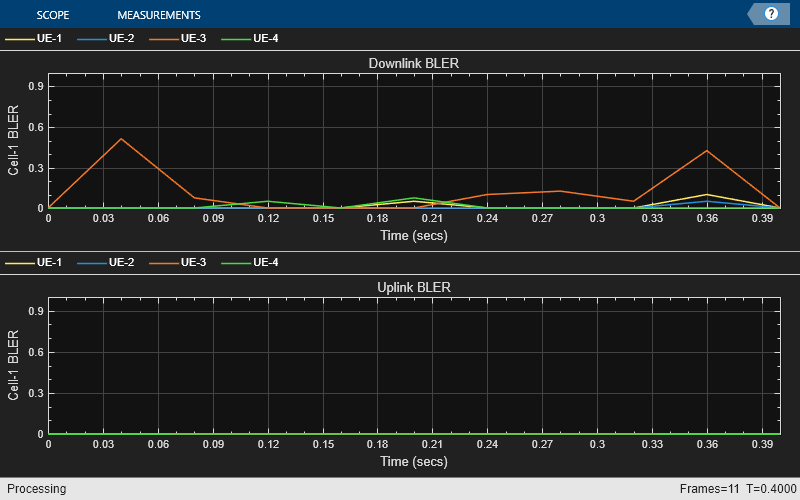

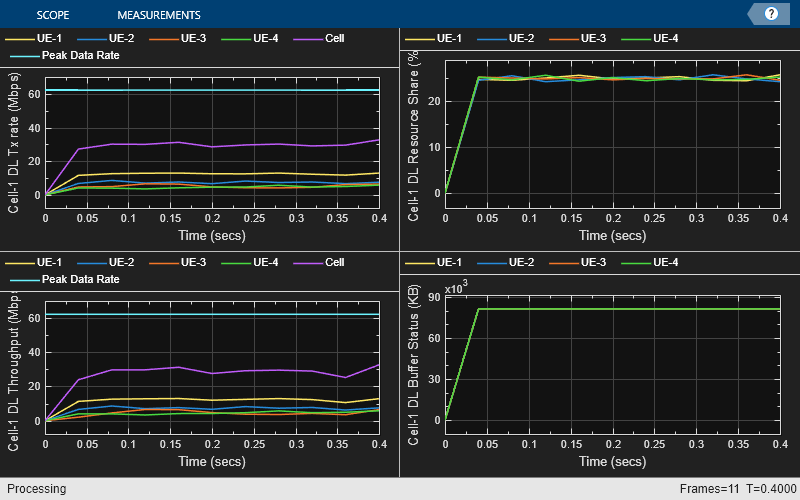

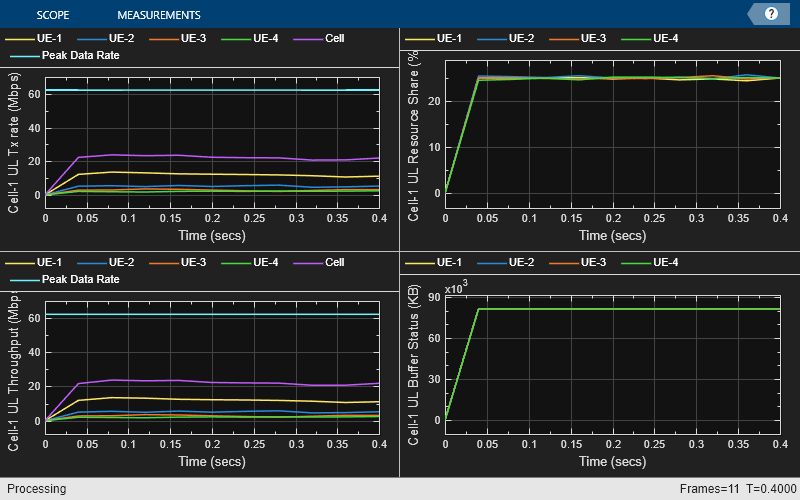

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation * 1e-2;

% Run the simulation
run(networkSimulator,simulationTime);

Retrieve per-node statistics.

gNBStats = statistics(gNB);
ueStats = statistics(UEs);

Compare the achieved values of the system performance indicators with their theoretical peak values, which assume zero overheads. The displayed performance indicators include the achieved data rate (UL and DL), spectral efficiency (UL and DL), and block error rate (UL and DL). This example calculates the theoretical peak value based on the specifications defined in the 3GPP TR 37.910. These specifications define the peak value as the total data bits a single mobile station can receive without errors, using all the radio resources available for either UL or DL. For additional details on peak data rate calculation, see [Simulation Visualization](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e).

displayPerformanceIndicators(metricsVisualizer)

Peak UL throughput: 62.21 Mbps. Achieved cell UL throughput: 22.21 Mbps
Achieved UL throughput for each UE: [12.04         5.18         2.88         2.11]
Peak UL spectral efficiency: 12.44 bits/s/Hz. Achieved UL spectral efficiency for cell: 4.44 bits/s/Hz 
Block error rate for each UE in the UL direction: [0  0  0  0]

Peak DL throughput: 62.21 Mbps. Achieved cell DL throughput: 28.80 Mbps
Achieved DL throughput for each UE: [12.29         7.35          4.6         4.56]
Peak DL spectral efficiency: 12.44 bits/s/Hz. Achieved DL spectral efficiency for cell: 5.76 bits/s/Hz
Block error rate for each UE in the DL direction: [0.015       0.005       0.128       0.013]



The simulation results show that the achieved throughput is significantly less than theoretical peak. This outcome is expected because the peak value assumes the use of the highest modulation-and-coding-scheme (MCS) for all the packets and no failures in packet reception. In contrast, the simulation selects an MCS that limits the packet error rate, based on channel quality measurements from reference signals (CSI-RS and SRS). In this scenario, the UEs are far from the gNB. Further, the example models the links with a CDL channel, leading to a dynamic selection of MCS.

Each UE receives about 25% of the resources, reflecting the behavior of a round-robin scheduling strategy with four UEs.

## Simulation Visualization and Logs

To evaluate the performance of the cell, the example includes various runtime visualizations. For further details on the runtime visualizations presented, refer to [Simulation Visualization](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e).

The example saves the simulation logs in a MAT-file for post-simulation analysis. For more information about the logged information, see the [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654) example.

if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct(DLTimeStepLogs=[],ULTimeStepLogs=[],...
            SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct(TimeStepLogs=[],SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Get the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Get the Phy reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

## Further Exploration

Try running the example with these modifications.

- Use abstract PHY and compare its performance with that of full PHY.

- Visualize the captured IQ samples. Capture the IQ samples by enabling the `enableIQSampleCapture` flag. To visualize the captured IQ samples, use the [`signalAnalyzer`](docid:signal_ref#bulfy0x) (Signal Processing Toolbox) app. For example, to visualize the IQ Samples captured at the gNB node, uncomment this code.

% if enableIQSampleCapture && strcmp(phyAbstractionType, "none")
%   signalAnalyzer(iqSampleObj(1).IQSamples);
% end

## Supporting Functions

The example uses these helpers:

- [`helperNRMetricsVisualizer`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','helperNRMetricsVisualizer')): Implements metrics visualization functionality

- [`helperNRSchedulingLogger`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','helperNRSchedulingLogger')): Implements scheduling information logging functionality

- [`helperNRPhyLogger`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','helperNRPhyLogger')): Implements PHY packet reception information logging functionality

- [`helperCaptureIQSamples`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','helperCaptureIQSamples')): Implements IQ sample capture functionality

- [`hNRCustomChannelModel`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','hNRCustomChannelModel')): Implements channel modeling functionality

- [`hNRCreateCDLChannels`](matlab:openExample('5g/NRCellPerformanceEvaluationWithPhysicalLayerIntegrationExample','supportingFile','hNRCreateCDLChannels'))`:` Creates CDL channels for gNB-to-UE and UE-to-gNB links

*Copyright 2020-2025 The MathWorks, Inc.*